# Hankel Matrix Completion

## Experimenting with LTI's without input

First we get an intuition of state space definition without input. We deal with discrete systems, since we are interested in data sampled at specific time points in history.

% statenum states, outputnum outputs, 0 input
statenum = 100;
outputnum = 1;

state_space = drss(statenum,outputnum,0)

state_space =
 
  A = 
                 x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22         x23         x24         x25         x26         x27         x28         x29         x30         x31         x32         x33         x34         x35         x36         x37         x38         x39         x40         x41         x42         x43         x44         x45         x46         x47         x48         x49         x50         x51         x52         x53         x54         x55         x56         x57         x58         x59         x60         x61         x62         x63         x64         x65         x66         x67         x68         x69         x70         x71         x72         x73         x74         x75         x76         x77         x78         x79         x80         x

state_space_properties(state_space)

State-space properties: 
    "Number of states: 100"
    "Number of inputs: 0"
    "Number of outputs: 1"

State-space dimensions: 
    "A_rows:100"    "A_cols:100"
    "B_rows:100"    "B_cols:0"  
    "C_rows:1"      "C_cols:100"
    "D_rows:1"      "D_cols:0"  

Max absolute eigen value: 0.99718
Eigen values of A: 
    0.9717
    0.9717
    0.9972
    0.9972
    0.9272
    0.9534
    0.9534
    0.8668
    0.8668
    0.8783
    0.9367
    0.7635
    0.7635
    0.8312
    0.8121
    0.9025
    0.8273
    0.8273
    0.8639
    0.6677
    0.6677
    0.7292
    0.7292
    0.6598
    0.5881
    0.5881
    0.6272
    0.7197
    0.5788
    0.5788
    0.6156
    0.6156
    0.5910
    0.5910
    0.7946
    0.7946
    0.6382
    0.5053
    0.5053
    0.5599
    0.6263
    0.6197
    0.3977
    0.3977
    0.3874
    0.3015
    0.3015
    0.2932
    0.2932
    0.3378
    0.3378
    0.3075
    0.3075
    0.3204
    0.3214
    0.3214
    0.2666
    0.2666
    0.2580
    0.2580
    0.3140
    0.2939

Now we create a set of outputs, with x(0) = x_0 != 0 (since we dont have an input and thus if the state is the zero vector the transfer function will not do anything to the state)

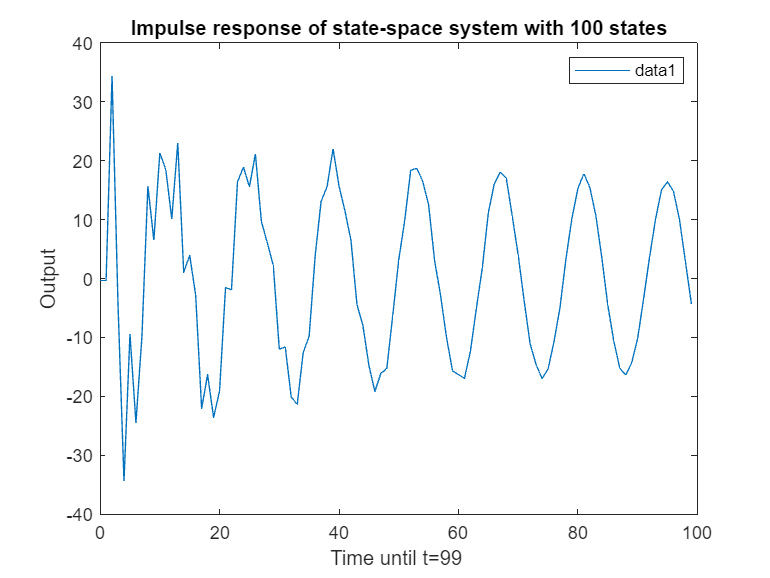

maxTime = 100;

state_space_sim(state_space,maxTime);

Notice that its possible for one of the eigenvalues to be exactly 1, which is neither stable nor unstable (marginally stable). Using the drss function we can generate many different kinds of discrete-time state-space systems that are stable. In the plot we observe that after a long enough time the impulse response stabilizes.

## Experimenting with LTI's with input

We can also generate an LTI with an input vector upon which a transformation B and D have an effect on the state change and output. We can have a single-input or multi-input.

% statenum states, outputnum outputs, inputnum input
statenum = 100;
outputnum = 1;
inputnum = 4;
maxTime = 100;
input = [2;1;2;3];


state_space = drss(statenum,outputnum,inputnum);
state_space_properties(state_space)

State-space properties: 
    "Number of states: 100"
    "Number of inputs: 4"
    "Number of outputs: 1"

State-space dimensions: 
    "A_rows:100"    "A_cols:100"
    "B_rows:100"    "B_cols:4"  
    "C_rows:1"      "C_cols:100"
    "D_rows:1"      "D_cols:4"  

Max absolute eigen value: 0.99429
Eigen values of A: 
    0.9943
    0.9943
    0.9781
    0.9781
    0.9290
    0.9290
    0.8974
    0.8974
    0.8761
    0.8761
    0.8339
    0.8339
    0.9892
    0.9818
    0.9730
    0.9695
    0.9203
    0.9203
    0.9357
    0.9497
    0.9143
    0.9143
    0.7819
    0.7819
    0.9179
    0.7919
    0.8185
    0.8202
    0.6183
    0.6183
    0.6171
    0.6171
    0.7400
    0.7548
    0.7303
    0.5210
    0.5210
    0.5153
    0.5153
    0.6605
    0.6414
    0.7765
    0.7765
    0.6124
    0.6124
    0.6287
    0.6282
    0.5965
    0.6062
    0.5391
    0.5639
    0.4885
    0.3484
    0.3484
    0.5053
    0.5173
    0.4424
    0.4124
    0.3326
    0.3326
    0.3181
    0.3181

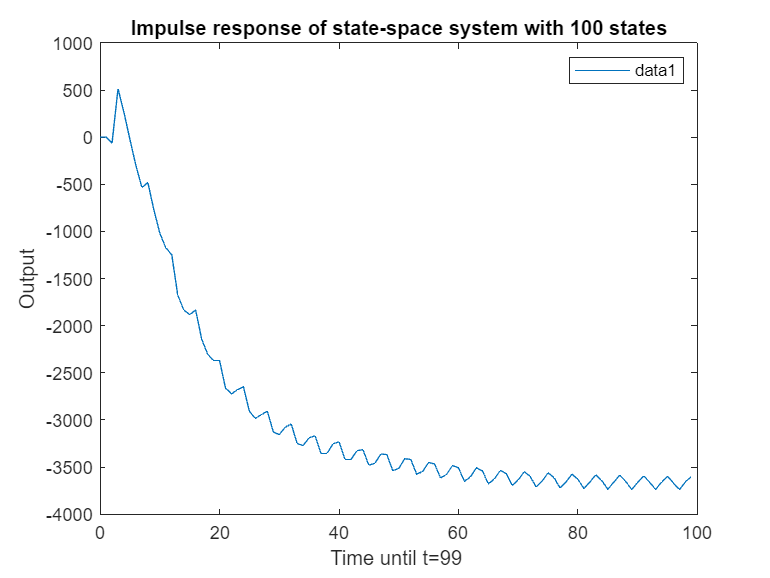

state_space_sim(state_space,maxTime,input);

## Experimenting with Hankel Matrices

## Experimenting with Hankel Matrix Completion